clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

Beh = obj.BehavTable;


## Progress based on trial

win = 40;
step = 5;
n_trials = 100;

id_control = find(Beh.Label=="Control");
id_chemo = find(Beh.Label=="Chemo");

id_l_fill = find(Beh.PortCorrect==1 & Beh.Cued==0 & Beh.Guided==1);
id_l_empty = find(Beh.PortCorrect==1 & Beh.Cued==0 & Beh.Guided==0);
id_r_fill = find(Beh.PortCorrect==2 & Beh.Cued==0 & Beh.Guided==1);
id_r_empty = find(Beh.PortCorrect==2 & Beh.Cued==0 & Beh.Guided==0);

id_l_fill = id_l_fill(id_l_fill<id_chemo(1));
id_l_empty = id_l_empty(id_l_empty<id_chemo(1));
id_r_fill = id_r_fill(id_r_fill<id_chemo(1));
id_r_empty = id_r_empty(id_r_empty<id_chemo(1));

hd_l_fill = Beh.HoldDuration(id_l_fill);
hd_l_empty = Beh.HoldDuration(id_l_empty);
hd_r_fill = Beh.HoldDuration(id_r_fill);
hd_r_empty = Beh.HoldDuration(id_r_empty);

[hd_l_fill_track, hd_l_fill_track_sem, hd_l_fill_track_id] = calTrack(hd_l_fill, win, step);
[hd_l_empty_track, hd_l_empty_track_sem, hd_l_empty_track_id] = calTrack(hd_l_empty, win, step);
[hd_r_fill_track, hd_r_fill_track_sem, hd_r_fill_track_id] = calTrack(hd_r_fill, win, step);
[hd_r_empty_track, hd_r_empty_track_sem, hd_r_empty_track_id] = calTrack(hd_r_empty, win, step);


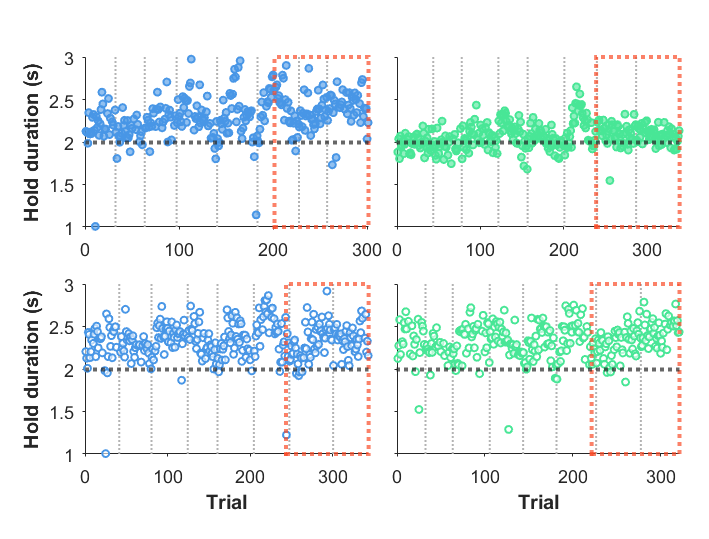


fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 9.5], 'Name', 'fill vs empty', 'Color', 'w');

%
ax_l_fill = axes(fig, 'Units', 'centimeters', 'Position', [1.5 5.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_l_fill = find(diff(double(Beh.SessionDate(id_l_fill)))~=0) + .5;
for i = 1:length(sep_l_fill)
    line(ax_l_fill, [sep_l_fill(i) sep_l_fill(i)], [1 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_l_fill, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_l_fill, 1:length(hd_l_fill), hd_l_fill, 12, ...
    'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

fill(ax_l_fill, length(hd_l_fill) + [-n_trials+0.5 0.5 0.5 -n_trials+0.5], [1 1 3 3], 'r', ...
    'FaceColor', 'none', 'EdgeColor', GPSColor.PhaseLate, 'LineStyle', ':', 'LineWidth', 2, 'EdgeAlpha', .7);

ax_l_fill.YLabel.String = "Hold duration (s)";
ax_l_fill.YLabel.FontWeight = "bold";
set(ax_l_fill, 'YLim', [1 3], 'XLim', [0 length(id_l_fill)+1]);

%
ax_l_empty = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_l_empty = find(diff(double(Beh.SessionDate(id_l_empty)))~=0) + .5;
for i = 1:length(sep_l_empty)
    line(ax_l_empty, [sep_l_empty(i) sep_l_empty(i)], [1 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_l_empty, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_l_empty, 1:length(hd_l_empty), hd_l_empty, 12, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

fill(ax_l_empty, length(hd_l_empty) + [-n_trials+0.5 0.5 0.5 -n_trials+0.5], [1 1 3 3], 'r', ...
    'FaceColor', 'none', 'EdgeColor', GPSColor.PhaseLate, 'LineStyle', ':', 'LineWidth', 2, 'EdgeAlpha', .7);

ax_l_empty.YLabel.String = "Hold duration (s)";
ax_l_empty.YLabel.FontWeight = "bold";
ax_l_empty.XLabel.String = "Trial";
ax_l_empty.XLabel.FontWeight = "bold";
set(ax_l_empty, 'YLim', [1 3], 'XLim', [0 length(id_l_empty)+1]);

%
ax_r_fill = axes(fig, 'Units', 'centimeters', 'Position', [7 5.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_r_fill = find(diff(double(Beh.SessionDate(id_r_fill)))~=0) + .5;
for i = 1:length(sep_r_fill)
    line(ax_r_fill, [sep_r_fill(i) sep_r_fill(i)], [1 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_r_fill, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_r_fill, 1:length(hd_r_fill), hd_r_fill, 12, ...
    'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

fill(ax_r_fill, length(hd_r_fill) + [-n_trials+0.5 0.5 0.5 -n_trials+0.5], [1 1 3 3], 'r', ...
    'FaceColor', 'none', 'EdgeColor', GPSColor.PhaseLate, 'LineStyle', ':', 'LineWidth', 2, 'EdgeAlpha', .7);

set(ax_r_fill, 'YLim', [1 3], 'XLim', [0 length(id_r_fill)+1], 'YTickLabel', []);

%
ax_r_empty = axes(fig, 'Units', 'centimeters', 'Position', [7 1.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

sep_r_empty = find(diff(double(Beh.SessionDate(id_r_empty)))~=0) + .5;
for i = 1:length(sep_r_empty)
    line(ax_r_empty, [sep_r_empty(i) sep_r_empty(i)], [1 3], 'LineStyle', ':', 'LineWidth', 1, 'Color', [.7 .7 .7]);
end

yline(ax_r_empty, 2, 'LineStyle', ':', 'LineWidth', 2);
scatter(ax_r_empty, 1:length(hd_r_empty), hd_r_empty, 12, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

fill(ax_r_empty, length(hd_r_empty) + [-n_trials+0.5 0.5 0.5 -n_trials+0.5], [1 1 3 3], 'r', ...
    'FaceColor', 'none', 'EdgeColor', GPSColor.PhaseLate, 'LineStyle', ':', 'LineWidth', 2, 'EdgeAlpha', .7);

ax_r_empty.XLabel.String = "Trial";
ax_r_empty.XLabel.FontWeight = "bold";
set(ax_r_empty, 'YLim', [1 3], 'XLim', [0 length(id_r_empty)+1], 'YTickLabel', []);

## PDF of last 100 trials for each condition

hd_l_fill_late = hd_l_fill(end-n_trials+1:end);
hd_l_empty_late = hd_l_empty(end-n_trials+1:end);
hd_r_fill_late = hd_r_fill(end-n_trials+1:end);
hd_r_empty_late = hd_r_empty(end-n_trials+1:end);


bins = .5:.001:3;
band_width = 0.12;
n_boot = 1000;
alpha_boot = 0.05;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width); % 
boot_pdf = @(x) bootci(n_boot, {kde_pdf, x}, 'type', 'cper', 'alpha', alpha_boot);


pdf_l_fill = kde_pdf(hd_l_fill_late);
pdf_l_empty = kde_pdf(hd_l_empty_late);
pdf_r_fill = kde_pdf(hd_r_fill_late);
pdf_r_empty = kde_pdf(hd_r_empty_late);

pdf_l_fill_ci = boot_pdf(hd_l_fill_late);
pdf_l_empty_ci = boot_pdf(hd_l_empty_late);
pdf_r_fill_ci = boot_pdf(hd_r_fill_late);
pdf_r_empty_ci = boot_pdf(hd_r_empty_late);


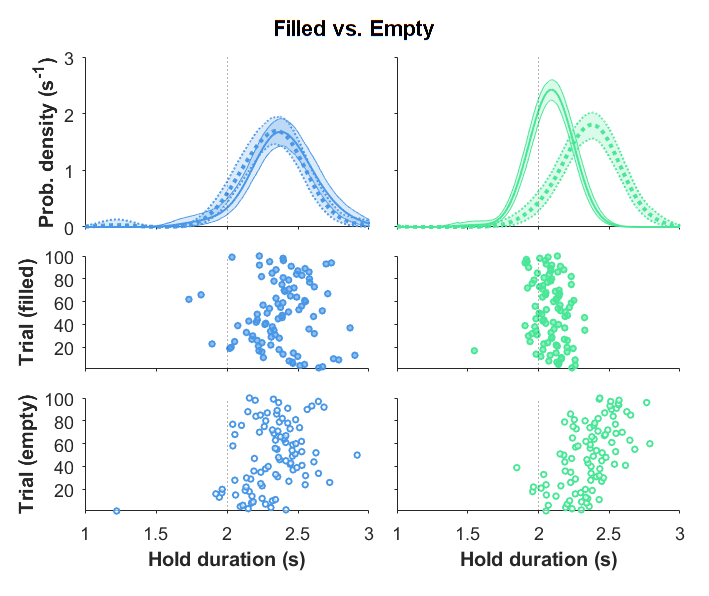

muHat_1 = 0.4791

sigmaHat_1 = 0.0224

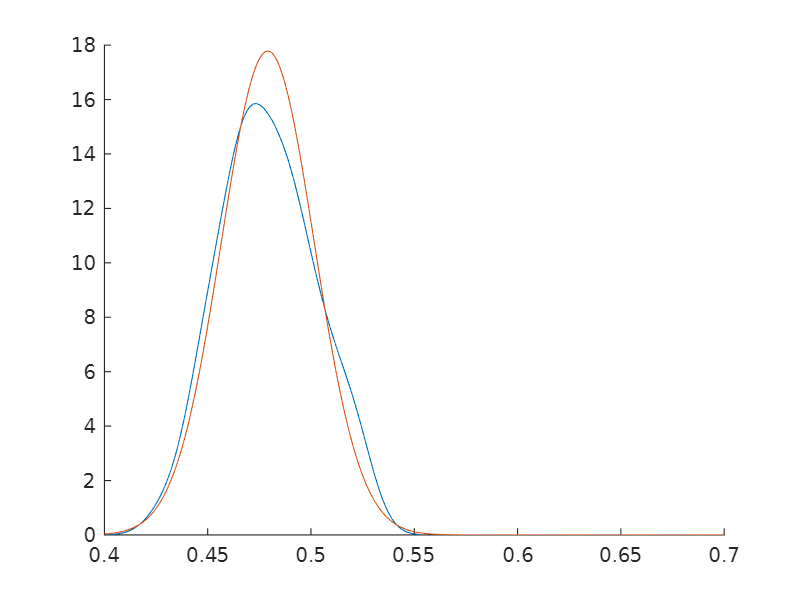

muHat_2 = 2.0919

sigmaHat_2 = 0.0978

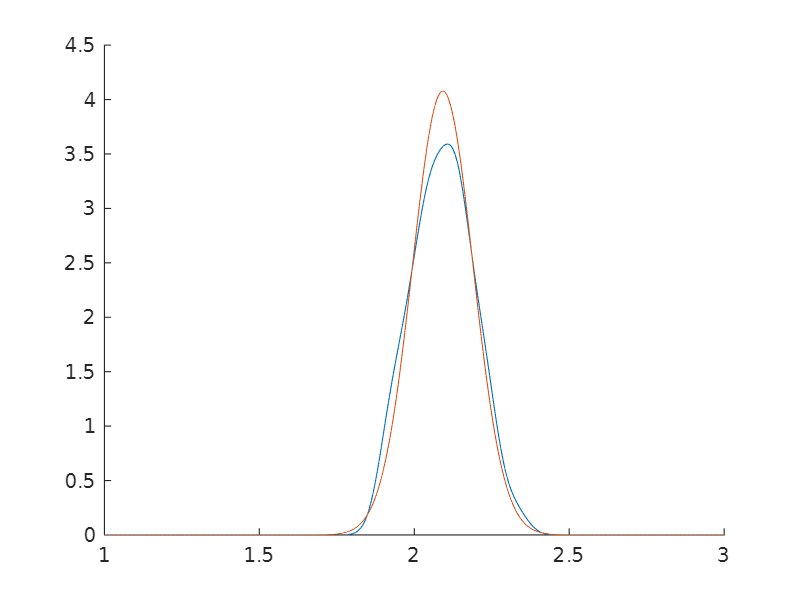

fig = figure(35); clf(35);
set(fig, 'Name', 'fill vs empty', 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 10.5], 'Color', 'w');

uicontrol('parent', fig, 'Style', 'text', 'units', 'centimeters', 'position', [1 fig.Position(4)-.75 fig.Position(3)-2 .5],...
        'string', "Filled vs. Empty", 'fontsize', 11, 'fontweight', 'bold', 'backgroundcolor', 'w');

%
ax_l_pdf = axes(fig, 'Units', 'centimeters', 'Position', [1.5 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_l_pdf, 2, 'LineWidth', .5, 'LineStyle', ':');
fill(ax_l_pdf, [bins flip(bins)], [pdf_l_fill_ci(1,:) flip(pdf_l_fill_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortL, 'FaceAlpha', 0.2, ...
    'EdgeColor', GPSColor.PortL, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_l_pdf, bins, pdf_l_fill, ...
    'color', GPSColor.PortL, 'linewidth', 1, 'LineStyle', '-');
fill(ax_l_pdf, [bins flip(bins)], [pdf_l_empty_ci(1,:) flip(pdf_l_empty_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortL, 'FaceAlpha', 0.2, ...
    'EdgeColor', GPSColor.PortL, 'LineStyle', ':', 'LineWidth', 1);
plot(ax_l_pdf, bins, pdf_l_empty, ...
    'color', GPSColor.PortL, 'linewidth', 2, 'LineStyle', ':');

ax_l_pdf.YLabel.String = "Prob. density (s^{-1})";
ax_l_pdf.YLabel.FontWeight = "bold";

set(ax_l_pdf, 'XLim', [1 3], 'XTickLabel', []);

%
ax_r_pdf = axes(fig, 'Units', 'centimeters', 'Position', [7 6.5 5 3], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_pdf, 2, 'LineWidth', .5, 'LineStyle', ':');
fill(ax_r_pdf, [bins flip(bins)], [pdf_r_fill_ci(1,:) flip(pdf_r_fill_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortR, 'FaceAlpha', 0.2, ...
    'EdgeColor', GPSColor.PortR, 'LineStyle', '-', 'LineWidth', .5);
plot(ax_r_pdf, bins, pdf_r_fill, ...
    'color', GPSColor.PortR, 'linewidth', 1, 'LineStyle', '-');
fill(ax_r_pdf, [bins flip(bins)], [pdf_r_empty_ci(1,:) flip(pdf_r_empty_ci(2,:))], 'y', ...
    'FaceColor', GPSColor.PortR, 'FaceAlpha', 0.2, ...
    'EdgeColor', GPSColor.PortR, 'LineStyle', ':', 'LineWidth', 1);
plot(ax_r_pdf, bins, pdf_r_empty, ...
    'color', GPSColor.PortR, 'linewidth', 2, 'LineStyle', ':');

set(ax_r_pdf, 'XLim', [1 3], 'XTickLabel', [], 'YTickLabel', []);

%
ax_l_pdf.YLim(2) = max([ax_l_pdf.YLim(2) ax_r_pdf.YLim(2)]);
ax_l_pdf.YLim(2) = (round(ax_l_pdf.YLim(2)) + ceil(ax_l_pdf.YLim(2))) / 2;
ax_r_pdf.YLim(2) = ax_l_pdf.YLim(2);

%
ax_l_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_l_fill_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

scatter(ax_l_fill_scatter, hd_l_fill_late, 1:n_trials, 8, ...
    'MarkerFaceColor', GPSColor.PortL, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_l_fill_scatter.YLabel.String = "Trial (filled)";
ax_l_fill_scatter.YLabel.FontWeight = "bold";

set(ax_l_fill_scatter, 'XLim', [1 3], 'XTickLabel', [], 'YLim', [1 n_trials], 'YTick', 0:20:n_trials);

%
ax_r_fill_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 4 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_fill_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

scatter(ax_r_fill_scatter, hd_r_fill_late, 1:n_trials, 8, ...
    'MarkerFaceColor', GPSColor.PortR, 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

set(ax_r_fill_scatter, 'XLim', [1 3], 'XTickLabel', [], 'YTickLabel', [], 'YLim', [1 n_trials], 'YTick', 0:20:n_trials);

%
ax_l_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [1.5 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_l_empty_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

scatter(ax_l_empty_scatter, hd_l_empty_late, 1:n_trials, 8, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortL, 'LineWidth', 1);

ax_l_empty_scatter.YLabel.String = "Trial (empty)";
ax_l_empty_scatter.YLabel.FontWeight = "bold";
ax_l_empty_scatter.XLabel.String = "Hold duration (s)";
ax_l_empty_scatter.XLabel.FontWeight = "bold";

set(ax_l_empty_scatter, 'XLim', [1 3], 'YLim', [1 n_trials], 'YTick', 0:20:n_trials);

%
ax_r_empty_scatter = axes(fig, 'Units', 'centimeters', 'Position', [7 1.5 5 2], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

xline(ax_r_empty_scatter, 2, 'LineWidth', .5, 'LineStyle', ':');

scatter(ax_r_empty_scatter, hd_r_empty_late, 1:n_trials, 8, ...
    'MarkerFaceColor', 'w', 'MarkerFaceAlpha', .6, ...
    'MarkerEdgeColor', GPSColor.PortR, 'LineWidth', 1);

ax_r_empty_scatter.XLabel.String = "Hold duration (s)";
ax_r_empty_scatter.XLabel.FontWeight = "bold";

set(ax_r_empty_scatter, 'XLim', [1 3], 'YTickLabel', [], 'YLim', [1 n_trials], 'YTick', 0:20:n_trials);

function [track_mean, track_sem, track_id] = calTrack(data, win, step)

track_mean = movmean(data, win, 'Endpoints', 'discard');
track_sem = movstd(data, win, 'Endpoints', 'discard') ./ sqrt(win);
track_id = 1:length(track_mean);
track_mean = track_mean(1:step:end);
track_sem = track_sem(1:step:end);
track_id = track_id(1:step:end);

end